# Example how to use functions from MLIB/CRS library: traveltime approximations in C++ 

**Author**: Abakumov Ivan

**University of Hamburg**

**E-mail**: [abakumov_ivan@mail.ru](mailto:abakumov_ivan@mail.ru)

**Publication date**: 31st August 2016

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Introduction

model = 41;
acquisition = 3;

## Get model parameters

Get_model_parameters;

## Get acquisition geometry

Get_model_acquisition_geometry;

## Load stacking parameters

 CRS_param = MLD([mlibfolder '/CRS/models/model_' num2str(model) '_CRS_param.mat']); 

 X0 = CRS_param.x0; 
 t0 = CRS_param.t0; 
 v0 = CRS_param.v0; 
 w3 = CRS_param.w; 
 M3 = CRS_param.M; 
 N3 = CRS_param.N; 
 
 w = w3(1:2, 1); 
 N = N3(1:2, 1:2);
 M = M3(1:2, 1:2);

## Traveltime approximations

HH = (Xg(1:2, :) - Xs(1:2,:))/2;
MM = (Xg(1:2, :) + Xs(1:2,:))/2;
MM(1,:) = MM(1,:) - X0(1); 
MM(2,:) = MM(2,:) - X0(2);

% prepare parameters for cpp functions
hx = HH(1,:); 
hy = HH(2,:); 
mx = MM(1,:); 
my = MM(2,:); 
hxhx = hx.*hx; 
hxhy = hx.*hy; 
hyhy = hy.*hy;
mxmx = mx.*mx; 
mxmy = mx.*my; 
mymy = my.*my; 

K = M/(M-N)*N;

attr(1,1) =   w(1);       %2/v0*sin(alpha)*cos(beta)
attr(2,1) =   w(2);       %2/v0*sin(alpha)*cos(beta)
attr(3,1) =   M(1,1); 
attr(4,1) =   M(1,2); 
attr(5,1) =   M(2,2); 
attr(6,1) =   K(1,1); 
attr(7,1) =   K(1,2); 
attr(8,1) =   K(2,2);
attr(9,1) =   t0; 
attr(10,1) =  v0;

## CRS

tti_crs     = Get_traveltime_3D_CRS (MM, HH, t0, w, M, N);
% mex Get_traveltime_3D_CRS_cpp.cpp
tti_crs_cpp = Get_traveltime_3D_CRS_cpp(attr,mx,my, hx, hy, mxmx, mxmy, mymy, hxhx, hxhy, hyhy);

dims: dims[0]=1, dims[1]=100


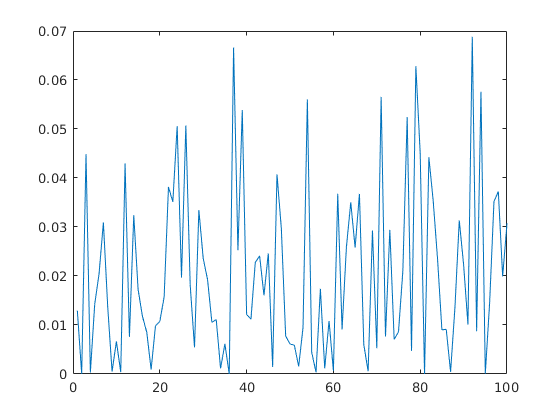

plot(tti_crs_cpp - tti_crs)

## DSR

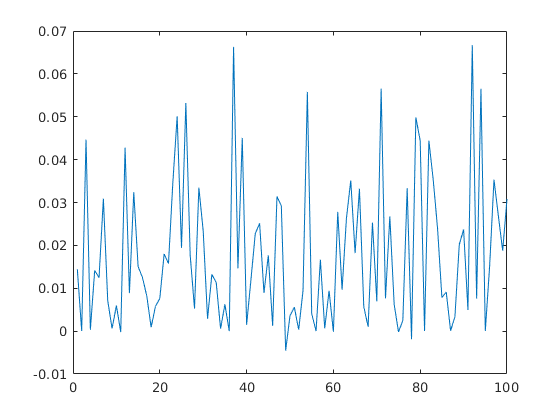

tti_dsr     = Get_traveltime_3D_DSR (MM, HH, t0, w, M, N);
%mex Get_traveltime_3D_DSR_cpp.cpp
tti_dsr_cpp = Get_traveltime_3D_DSR_cpp(attr,mx,my, hx, hy, mxmx, mxmy, mymy, hxhx, hxhy, hyhy);
plot(tti_dsr_cpp - tti_dsr)

## nCRS

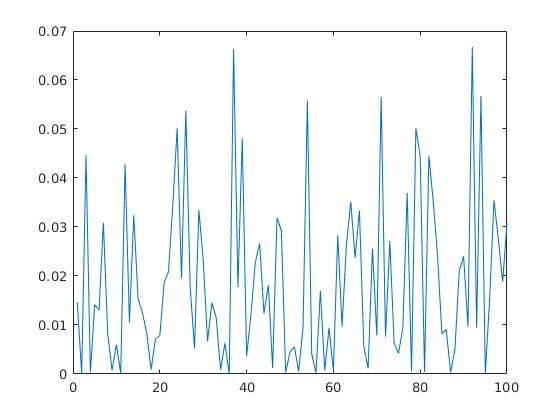

tti_ncrs     = Get_traveltime_3D_nCRS (MM, HH, t0, w, M, N);
% mex Get_traveltime_3D_nCRS_cpp.cpp
tti_ncrs_cpp = Get_traveltime_3D_nCRS_cpp(attr,mx,my, hx, hy, mxmx, mxmy, mymy, hxhx, hxhy, hyhy);
plot(tti_ncrs_cpp - tti_ncrs)

## iCRS

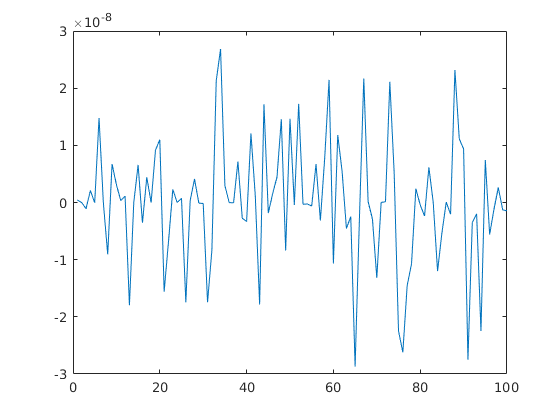

tti_icrs     = Get_traveltime_3D_iCRS_par_LIA (MM, HH, t0, w, M, N, 3);
% mex Get_traveltime_3D_iCRS_cpp.cpp
tti_icrs_cpp = Get_traveltime_3D_iCRS_cpp(attr,mx,my, hx, hy, mxmx, mxmy, mymy, hxhx, hxhy, hyhy);
plot(tti_icrs_cpp - tti_icrs(3,:))